MOMENTUM-BASED ESTIMATOR

clear all
clc

load('ws_homework_3_2025.mat')

% Parametri generali
n = 4;
m = 1.5;
Ib = diag([1.2416 1.2416 2*1.2416]);
r = 2;
T_s = 0.001;
g = 9.81;
t = attitude.time;
f_ext = [1; 1; 0];
tau_ext = [0; 0; -0.4];

e_3 = [0 0 1]';
p_dot_b = linear_vel.signals.values;
eta_b = attitude.signals.values;
eta_dot_b = attitude_vel.signals.values;
thrust = thrust.signals.values;
tau = tau.signals.values;

c0_values = [1, 5, 10, 25, 50, 100];
colors = lines(length(c0_values));
labels = arrayfun(@(x) sprintf('$c_0 = %d$', x), c0_values, 'UniformOutput', false);

external_wrench_all = cell(length(c0_values),1);

for idx = 1:length(c0_values)
    c_0 = c0_values(idx);
    k_0 = c_0;

    % Calcolo coefficienti filtro
    s = tf('s');
    G = (k_0/(s+c_0))^r;
    c = cell2mat(G.Denominator);

    Ki = zeros(r,1);
    prod_K = 1;
    k = 1;
    for j = r-1:-1:0
        Ki(j+1) = c(k+1) / prod_K;  
        prod_K = prod_K*Ki(j+1);
        k = k+1;
    end

    % Estimator variables
    external_wrench = zeros(6, length(t));
    gamma = zeros(6, length(t), r);

    for k = 1:length(t)-1
        [C, Q, R_b, M] = compute_param(eta_b(k,:), eta_dot_b(k,:), Ib);
        q(:,k+1) = [m*eye(3) zeros(3,3); zeros(3,3) M]*[p_dot_b(k+1,:) eta_dot_b(k+1,:)]';
        for i = 1:r
            if i == 1
                gamma(:,k+1,1) = gamma(:,k,i) + Ki(1)*((q(:,k+1) - q(:,k)) - T_s*(external_wrench(:,k) + [m*g*e_3-thrust(k)*R_b*e_3; C'*eta_dot_b(k,:)' + Q'*tau(k,:)']));
            else
                gamma(:,k+1,i) = gamma(:,k,i) + Ki(i)*T_s*(-external_wrench(:,k) + gamma(:,k,i-1));
            end
        end
        external_wrench(:,k+1) = gamma(:,k+1,r);
    end
    external_wrench_all{idx} = external_wrench;
end

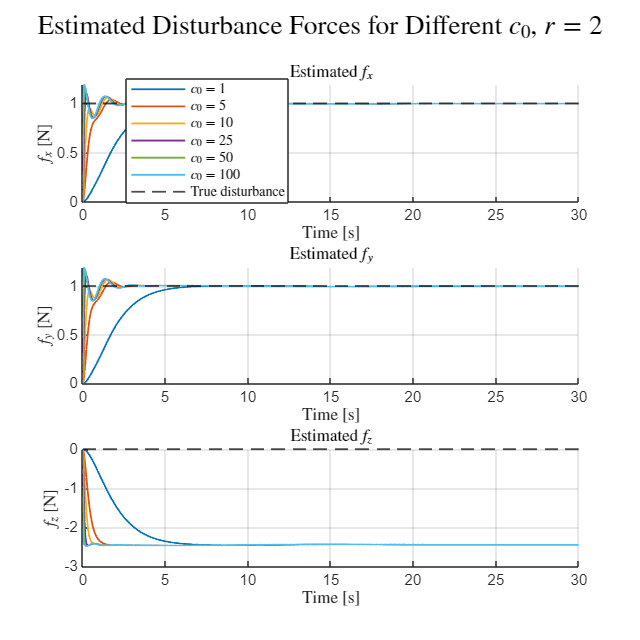

component_labels_f = {'$f_x$', '$f_y$', '$f_z$'};
ylabels_f = {'[N]', '[N]', '[N]'};
true_disturbance_f = {1, 1, 0};
true_line_style = {'--k', '--k', '--k'};

figure('Name','Estimated Disturbance Forces','Color','w','Position',[100 100 900 900]);
for i = 1:3
    subplot(3,1,i); hold on;
    for idx = 1:length(c0_values)
        plot(t, external_wrench_all{idx}(i,:), 'LineWidth', 1, 'Color', colors(idx,:));
    end
    yline(true_disturbance_f{i}, true_line_style{i}, 'LineWidth', 1, 'DisplayName','True disturbance');
  
    xlabel('Time [s]', 'Interpreter', 'latex');
    ylabel([component_labels_f{i} ' ' ylabels_f{i}], 'Interpreter', 'latex');
    title(['Estimated ' component_labels_f{i}], 'Interpreter', 'latex');
    grid on;
    if i == 1
        legend([labels, {'True disturbance'}],'Interpreter','latex','Location','best');
    end
end
sgtitle(sprintf('Estimated Disturbance Forces for Different $c_0$, $r = %d$', r), 'Interpreter', 'latex');
set(gcf,'PaperPositionMode','auto');
print(gcf,'-dpdf','ex3_disturbance_forces_c0_2.pdf','-bestfit');

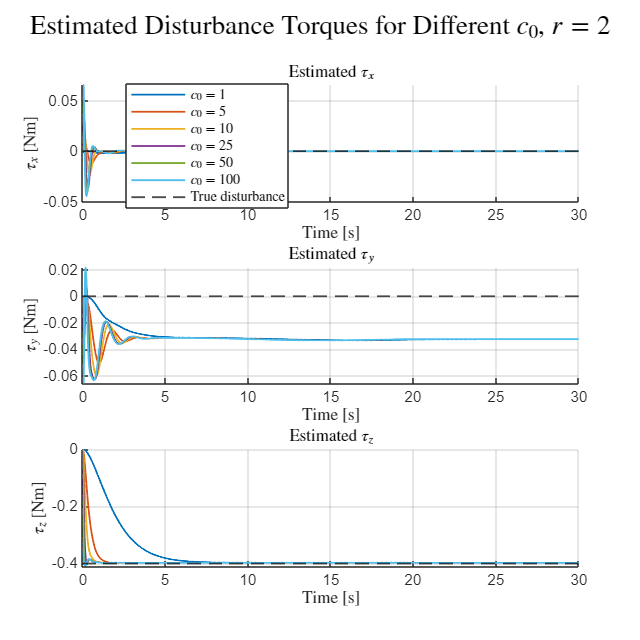


component_labels_tau = {'$\tau_x$', '$\tau_y$', '$\tau_z$'};
ylabels_tau = {'[Nm]', '[Nm]', '[Nm]'};
true_disturbance_tau = {0, 0, -0.4}; 

figure('Name','Estimated Disturbance Torques','Color','w','Position',[100 100 900 900]);
for i = 1:3
    subplot(3,1,i); hold on;
    for idx = 1:length(c0_values)
        plot(t, external_wrench_all{idx}(i+3,:), 'LineWidth', 1, 'Color', colors(idx,:));
    end

    yline(true_disturbance_tau{i}, '--k', 'LineWidth', 1, 'DisplayName','True disturbance');

    xlabel('Time [s]', 'Interpreter', 'latex');
    ylabel([component_labels_tau{i} ' ' ylabels_tau{i}], 'Interpreter', 'latex');
    title(['Estimated ' component_labels_tau{i}], 'Interpreter', 'latex');
    grid on;
    if i == 1
        legend([labels, {'True disturbance'}],'Interpreter','latex','Location','best');
    end
end
sgtitle(sprintf('Estimated Disturbance Torques for Different $c_0$, $r = %d$', r), 'Interpreter', 'latex');
set(gcf,'PaperPositionMode','auto');
print(gcf,'-dpdf','ex3_disturbance_torques_c0_2.pdf','-bestfit');

clear all
clc

load('ws_homework_3_2025.mat')

% Parametri generali
m = 1.5;
Ib = diag([1.2416 1.2416 2*1.2416]);
T_s = 0.001;
g = 9.81;
t = attitude.time;
e_3 = [0 0 1]';

p_dot_b = linear_vel.signals.values;
eta_b = attitude.signals.values;
eta_dot_b = attitude_vel.signals.values;
thrust = thrust.signals.values;
tau = tau.signals.values;

r_values = 1:5;
colors = lines(length(r_values));
labels = arrayfun(@(x) sprintf('$r = %d$', x), r_values, 'UniformOutput', false);

c_0 = 10; 

external_wrench_all = cell(length(r_values),1);

for idx = 1:length(r_values)
    r = r_values(idx);
    k_0 = c_0;

    % Calcolo coefficienti filtro
    s = tf('s');
    G = (k_0/(s+c_0))^r;
    c = cell2mat(G.Denominator);

    Ki = zeros(r,1);
    prod_K = 1;
    k = 1;
    for j = r-1:-1:0
        Ki(j+1) = c(k+1) / prod_K;  
        prod_K = prod_K*Ki(j+1);
        k = k+1;
    end

    % Estimator variables
    external_wrench = zeros(6, length(t));
    gamma = zeros(6, length(t), r);

    for k = 1:length(t)-1
        [C, Q, R_b, M] = compute_param(eta_b(k,:), eta_dot_b(k,:), Ib);
        q(:,k+1) = [m*eye(3) zeros(3,3); zeros(3,3) M]*[p_dot_b(k+1,:) eta_dot_b(k+1,:)]';
        for i = 1:r
            if i == 1
                gamma(:,k+1,1) = gamma(:,k,1) + Ki(1)*((q(:,k+1) - q(:,k)) - T_s*(external_wrench(:,k) + [m*g*e_3-thrust(k)*R_b*e_3; C'*eta_dot_b(k,:)' + Q'*tau(k,:)']));
            else
                gamma(:,k+1,i) = gamma(:,k,i) + Ki(i)*T_s*(-external_wrench(:,k) + gamma(:,k,i-1));
            end
        end
        external_wrench(:,k+1) = gamma(:,k+1,r);
    end
    external_wrench_all{idx} = external_wrench;
end

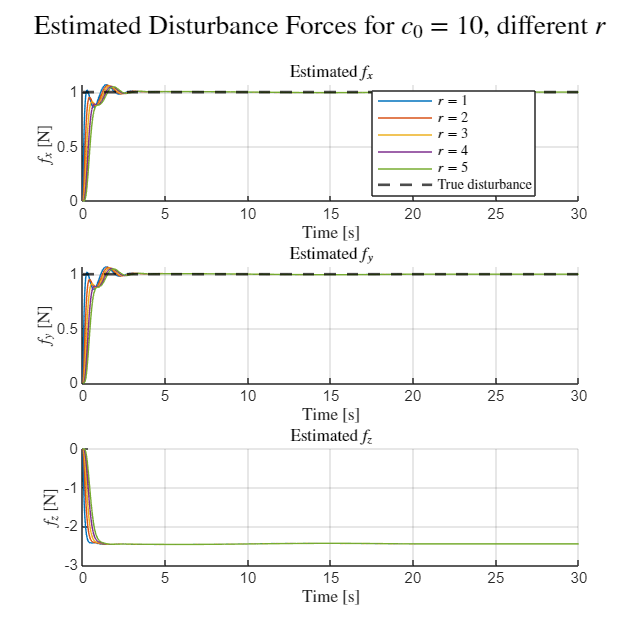

component_labels_tau = {'$\tau_x$', '$\tau_y$', '$\tau_z$'};
ylabels_tau = {'[Nm]', '[Nm]', '[Nm]'};
true_disturbance_tau = [0, 0, -0.4];

component_labels_f = {'$f_x$', '$f_y$', '$f_z$'};
ylabels_f = {'[N]', '[N]', '[N]'};
true_disturbance_f = {1, 1, 0};
true_line_style = {'--k', '--k', '--k'};

figure('Name','Estimated Disturbance Forces','Color','w','Position',[100 100 900 900]);
for i = 1:3
    subplot(3,1,i); hold on;
    for idx = 1:length(r_values)
        plot(t, external_wrench_all{idx}(i,:), 'LineWidth', 0.5, 'Color', colors(idx,:));
    end
    if true_disturbance_f{i} ~= 0
        yline(true_disturbance_f{i}, true_line_style{i}, 'LineWidth', 1.5, 'DisplayName','True disturbance');
    end
    xlabel('Time [s]', 'Interpreter', 'latex');
    ylabel([component_labels_f{i} ' ' ylabels_f{i}], 'Interpreter', 'latex');
    title(['Estimated ' component_labels_f{i}], 'Interpreter', 'latex');
    grid on;
    if i == 1
        legend([labels, {'True disturbance'}],'Interpreter','latex','Location','best');
    end
end
sgtitle('Estimated Disturbance Forces for $c_0=10$, different $r$', 'Interpreter', 'latex');
set(gcf,'PaperPositionMode','auto');
print(gcf,'-dpdf','ex3_disturbance_forces_r.pdf','-bestfit');


figure('Name','Estimated Disturbance Torques','Color','w','Position',[100 100 900 900]);
for i = 1:3
    subplot(3,1,i); hold on;
    for idx = 1:length(r_values)
        plot(t, external_wrench_all{idx}(i+3,:), 'LineWidth', 0.5, 'Color', colors(idx,:));
    end
    if true_disturbance_tau(i) ~= 0
        yline(true_disturbance_tau(i), '--k', 'LineWidth', 1.5, 'DisplayName','True disturbance');
    end
    xlabel('Time [s]', 'Interpreter', 'latex');
    ylabel([component_labels_tau{i} ' ' ylabels_tau{i}], 'Interpreter', 'latex');
    title(['Estimated ' component_labels_tau{i}], 'Interpreter', 'latex');
    grid on;
    if i == 1
        legend([labels, {'True disturbance'}],'Interpreter','latex','Location','best');
    end
end

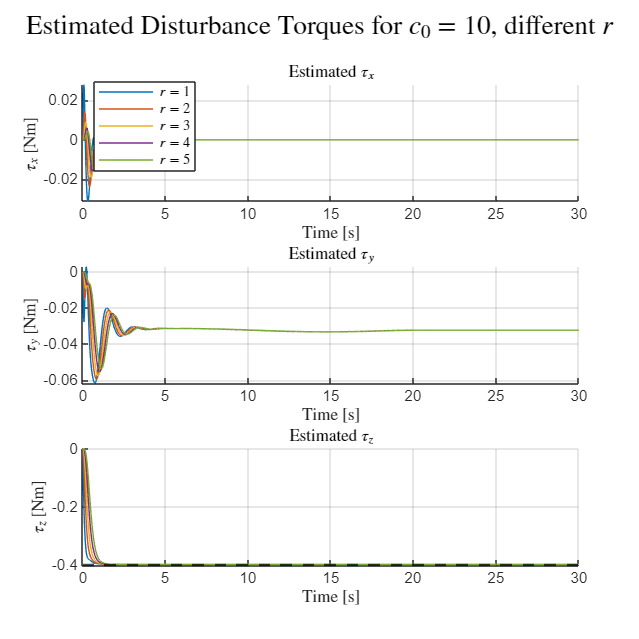

sgtitle(sprintf('Estimated Disturbance Torques for $c_0=10$, different $r$'),'Interpreter','latex');
set(gcf,'PaperPositionMode','auto');
print(gcf,'-dpdf','ex3_disturbance_torques_r.pdf','-bestfit');

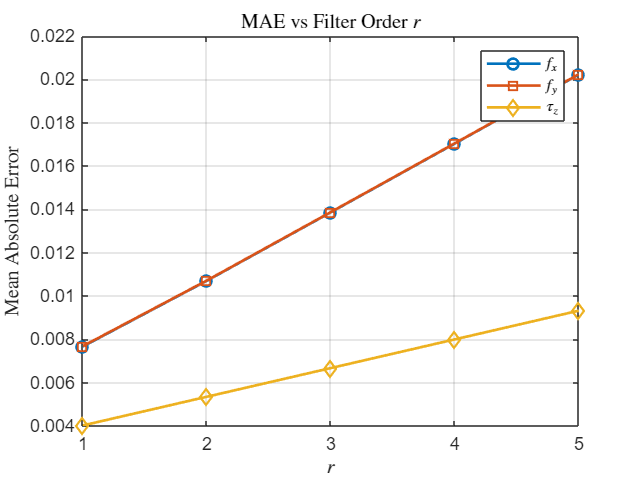



true_fx = 1;
true_fy = 1;
true_tauz = -0.4;
N = length(t);
MAE_fx = zeros(length(r_values),1);
MAE_fy = zeros(length(r_values),1);
MAE_tauz = zeros(length(r_values),1);

e_fx = zeros(length(r_values),N);
e_fy = zeros(length(r_values),N);
e_tauz = zeros(length(r_values),N);

for idx = 1:length(r_values)
    fx_est = external_wrench_all{idx}(1,:); % estimated force x
    fy_est = external_wrench_all{idx}(2,:); % estimated force y
    tauz_est = external_wrench_all{idx}(6,:); % estimated torque z
    
    e_fx(idx,:) = fx_est - true_fx;
    e_fy(idx,:)= fy_est - true_fy;
    e_tauz(idx,:) = tauz_est - true_tauz;

    MAE_fx(idx) = mean(abs(e_fx(idx,:)));
    MAE_fy(idx) = mean(abs(e_fy(idx,:)));
    MAE_tauz(idx) = mean(abs(e_tauz(idx,:)));
end

figure;
plot(r_values, MAE_fx, '-o', 'LineWidth', 1.5); hold on;
plot(r_values, MAE_fy, '-s', 'LineWidth', 1.5);
plot(r_values, MAE_tauz, '-d', 'LineWidth', 1.5);
xlabel('$r$', 'Interpreter', 'latex');
ylabel('Mean Absolute Error', 'Interpreter', 'latex');
legend({'$f_x$', '$f_y$', '$\tau_z$'}, 'Interpreter', 'latex');
title('MAE vs Filter Order $r$', 'Interpreter', 'latex');
grid on;
set(gcf,'PaperPositionMode','auto');
print(gcf,'-dpdf','ex3_MAE_r.pdf','-bestfit');

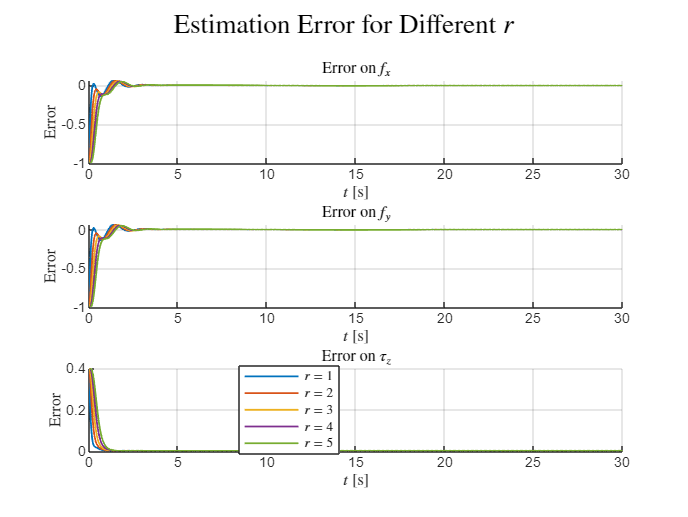

idx_plot = 1:length(r_values); 
colors = lines(length(idx_plot));

figure;
subplot(3,1,1)
hold on;
for k = idx_plot
    plot(t, e_fx(k,:), 'LineWidth', 1, 'Color', colors(k,:), ...
        'DisplayName', sprintf('$r=%d$', r_values(k)));
end
xlabel('$t$ [s]', 'Interpreter', 'latex');
ylabel('Error', 'Interpreter', 'latex');
title('Error on $f_x$', 'Interpreter', 'latex');
grid on;
subplot(3,1,2)
hold on;
for k = idx_plot
    plot(t, e_fy(k,:), 'LineWidth', 1, 'Color', colors(k,:), ...
        'DisplayName', sprintf('$r=%d$', r_values(k)));
end
xlabel('$t$ [s]', 'Interpreter', 'latex');
ylabel('Error', 'Interpreter', 'latex');
title('Error on $f_y$', 'Interpreter', 'latex');
grid on;
subplot(3,1,3)
hold on;
for k = idx_plot
    plot(t, e_tauz(k,:), 'LineWidth', 1, 'Color', colors(k,:), ...
        'DisplayName', sprintf('$r=%d$', r_values(k)));
end
xlabel('$t$ [s]', 'Interpreter', 'latex');
ylabel('Error', 'Interpreter', 'latex');
title('Error on $\tau_z$', 'Interpreter', 'latex');
legend('Interpreter', 'latex', 'Location', 'best');
grid on;

sgtitle('Estimation Error for Different $r$', 'Interpreter', 'latex');
set(gcf,'PaperPositionMode','auto');
print(gcf,'-dpdf','ex3_error_r.pdf','-bestfit');

% Soglie di convergenza (3% del valore reale)
threshold_fx = 0.03 * abs(true_fx);       
threshold_fy = 0.03 * abs(true_fy);       
threshold_tz = 0.03 * abs(true_tauz);     

N = length(t);

err_fx = zeros(length(r_values), N);
err_fy = zeros(length(r_values), N);
err_tz = zeros(length(r_values), N);

convergence_time_fx = zeros(length(r_values),1);
convergence_time_fy = zeros(length(r_values),1);
convergence_time_tz = zeros(length(r_values),1);

stable_window = round(2 / T_s);

for idx = 1:length(r_values)
    fx_est = external_wrench_all{idx}(1,:);
    fy_est = external_wrench_all{idx}(2,:);
    tz_est = external_wrench_all{idx}(6,:);
    
    err_fx(idx, :) = fx_est - true_fx;
    err_fy(idx, :) = fy_est - true_fy;
    err_tz(idx, :) = tz_est - true_tauz;
    
    compute_convergence = @(err, threshold) ...
        find( movmax(err, [stable_window stable_window*2]) <= threshold, 1 ) * T_s;
    
    convergence_time_fx(idx) = compute_convergence(err_fx(idx, :), threshold_fx);
    convergence_time_fy(idx) = compute_convergence(err_fy(idx, :), threshold_fy);
    convergence_time_tz(idx) = compute_convergence(err_tz(idx, :), threshold_tz);
end

convergence_time_fx(isnan(convergence_time_fx)) = t(end);
convergence_time_fy(isnan(convergence_time_fy)) = t(end);
convergence_time_tz(isnan(convergence_time_tz)) = t(end);

figure('Name','Convergence Time Analysis','Color','w','Position',[100 100 1200 800]);
subplot(2,1,1)
plot(r_values, convergence_time_fx, '-o', 'LineWidth', 1.5); hold on;
plot(r_values, convergence_time_fy, '-s', 'LineWidth', 1.5);
xlabel('$r$', 'Interpreter', 'latex');
ylabel('Convergence Time [s]', 'Interpreter', 'latex');
legend({'$f_x$', '$f_y$', '$f_z$'}, 'Interpreter', 'latex');

title('Forces Convergence Time', 'Interpreter', 'latex');
grid on;
subplot(2,1,2)
plot(r_values, convergence_time_tz, '-d', 'LineWidth', 1.5);
xlabel('$r$', 'Interpreter', 'latex');
ylabel('Convergence Time [s]', 'Interpreter', 'latex');
legend({'$\tau_x$', '$\tau_y$', '$\tau_z$'}, 'Interpreter', 'latex');

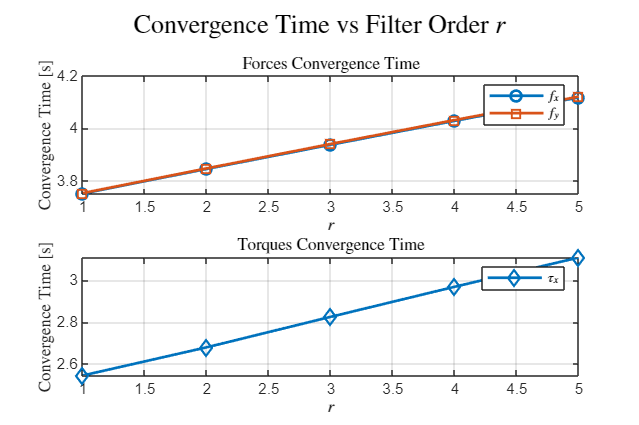

title('Torques Convergence Time', 'Interpreter', 'latex');
grid on;
sgtitle('Convergence Time vs Filter Order $r$', 'Interpreter', 'latex');
set(gcf,'PaperPositionMode','auto');
print(gcf,'-dpdf','ex3_convergence_time_all.pdf','-bestfit');

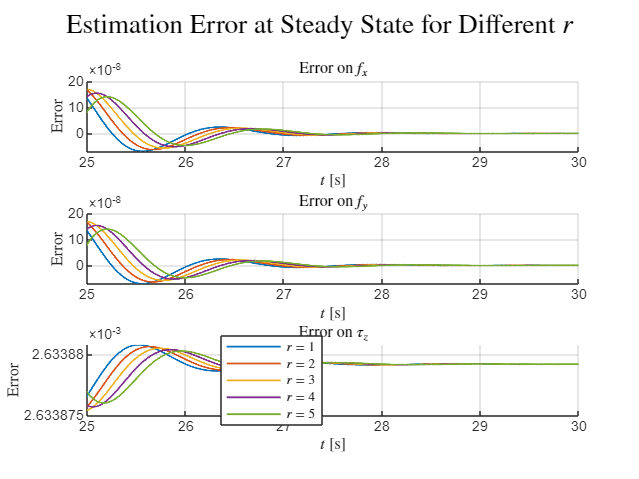



figure;
subplot(3,1,1)
hold on;
for idx=1:length(r_values)
plot(t, err_fx(idx, :), 'LineWidth', 1, 'DisplayName', sprintf('$r=%d$', r_values(idx)));
end
xlabel('$t$ [s]', 'Interpreter', 'latex');
xlim([25,30])
ylabel('Error', 'Interpreter', 'latex');
title('Error on $f_x$', 'Interpreter', 'latex');
grid on;
subplot(3,1,2)
hold on;
for idx=1:length(r_values)
plot(t, err_fy(idx, :), 'LineWidth', 1, 'DisplayName', sprintf('$r=%d$', r_values(idx)));
end
xlabel('$t$ [s]', 'Interpreter', 'latex');
xlim([25,30])
ylabel('Error', 'Interpreter', 'latex');
title('Error on $f_y$', 'Interpreter', 'latex');
grid on;
subplot(3,1,3)
hold on;
for idx=1:length(r_values)
plot(t, err_tz(idx, :), 'LineWidth', 1, 'DisplayName', sprintf('$r=%d$', r_values(idx)));
end
xlabel('$t$ [s]', 'Interpreter', 'latex');
xlim([25,30])
ylabel('Error', 'Interpreter', 'latex');
title('Error on $\tau_z$', 'Interpreter', 'latex');
legend('Interpreter', 'latex', 'Location', 'best');
grid on;

sgtitle('Estimation Error at Steady State for Different $r$', 'Interpreter', 'latex');
set(gcf,'PaperPositionMode','auto');
print(gcf,'-dpdf','ex3_error_regime_r.pdf','-bestfit');

for i = 1:r
    [err_max_tauz(i), idx_max_tz(i)] = max(err_tz(i, 25000:end));
    [err_max_fx(i), idx_max_fx(i)] = max(err_fx(i, 25000:end));
    [err_max_fy(i), idx_max_fy(i)] = max(err_fy(i, 25000:end));
end
disp(err_max_tauz);

   0.002633880761213   0.002633880615723   0.002633880483493   0.002633880363335   0.002633880254139



disp(err_max_fx);

   1.0e-06 *

   0.132517213868866   0.164746832176377   0.168812706036192   0.153803231706107   0.139914630992166



disp(err_max_fy);

   1.0e-06 *

   0.131980312900737   0.164600948870941   0.168662044996992   0.153426868099160   0.139336673754542



fz_est = external_wrench_all{idx}(3,:);
m_UAV_tilde = fz_est(end)/g

m_UAV_tilde = -0.2500

m_UAV = m + m_UAV_tilde 

m_UAV = 1.2500